fprintf('============================================================\n');

fprintf('GM(1,1)灰色预测模型 - GDP增长预测案例\n');

GM(1,1)灰色预测模型 - GDP增长预测案例


fprintf('============================================================\n\n');

% 案例背景与数据准备
fprintf('案例背景:\n');

案例背景:


fprintf('某地区2015-2021年GDP数据（单位：亿元），需要预测2022-2024年的GDP增长情况\n\n');

某地区2015-2021年GDP数据（单位：亿元），需要预测2022-2024年的GDP增长情况




% 原始数据
gdp_data = [1416, 1414, 1412, 1411, 1409];
years = 2017:2021;

fprintf('原始数据展示:\n');

原始数据展示:


disp(table(years', gdp_data', 'VariableNames', {'年份', 'GDP(亿元)'}));

    年份    GDP(亿元)
    ____    _________
    2017      1416   
    2018      1414   
    2019      1412   
    2020      1411   
    2021      1409   


% 数据基本统计
fprintf('\n 数据基本统计:\n');


 数据基本统计:


fprintf('数据量: %d个\n', length(gdp_data));

数据量: 5个


fprintf('平均值: %.2f亿元\n', mean(gdp_data));

平均值: 1412.40亿元


fprintf('标准差: %.2f亿元\n', std(gdp_data));

标准差: 2.70亿元


growth_rate = (gdp_data(end)/gdp_data(1))^(1/(length(gdp_data)-1)) - 1;
fprintf('增长率: %.2f%%（年均）\n', growth_rate*100);

增长率: -0.12%（年均）


% =============================================================================
% GM(1,1)模型实现函数
% =============================================================================

% 级比检验函数
function [valid, level_ratios, bounds] = level_ratio_test(data)
    n = length(data);
    level_ratios = zeros(1, n-1);
    
    % 计算级比
    for i = 2:n
        if data(i) ~= 0
            level_ratios(i-1) = data(i-1) / data(i);
        end
    end
    
    % 计算检验边界
    lower_bound = exp(-2/(n+1));
    upper_bound = exp(2/(n+1));
    bounds = [lower_bound, upper_bound];
    
    % 检验是否在合理范围内
    valid = all(level_ratios >= lower_bound & level_ratios <= upper_bound);
    
    fprintf('\n级比检验结果:\n');
    fprintf('检验边界: (%.3f, %.3f)\n', lower_bound, upper_bound);
    fprintf('级比序列: ');
    fprintf('%.3f ', level_ratios);
end

% GM(1,1)模型拟合函数
function [a, b, x0, x1] = gm11_fit(data)
    x0 = data(:);  % 原始数据序列(列向量)
    n = length(x0);
    
    fprintf('\n原始数据: ');
    fprintf('%.1f ', x0);
    fprintf('\n');
    
    % 级比检验
    [valid, ~, ~] = level_ratio_test(data);
    if ~valid
        fprintf('警告：数据未通过级比检验，模型预测精度可能较低！\n');
    end
    
    % 一次累加生成
    x1 = cumsum(x0);
    fprintf('累加生成序列: ');
    fprintf('%.1f ', x1);
    fprintf('\n');
    
    % 构造均值序列Z(1)
    z1 = zeros(n-1, 1);
    for i = 2:n
        z1(i-1) = 0.5 * (x1(i) + x1(i-1));
    end
    fprintf('均值序列Z(1): ');
    fprintf('%.1f ', z1);
    fprintf('\n');
    
    % 构造数据矩阵B和向量Y
    B = [-z1, ones(n-1, 1)];
    Y = x0(2:end);
    
    fprintf('\n数据矩阵B形状: %dx%d\n', size(B));
    fprintf('数据矩阵B:\n');
    disp(B);
    fprintf('观测向量Y: ');
    disp(Y');
    
    % 最小二乘估计参数
    try
        params = (B' * B) \ (B' * Y);  % 最小二乘求解
        a = params(1);
        b = params(2);
    catch
        error(' 参数估计失败，请检查数据质量');
    end
    
    fprintf('\n模型参数估计结果:\n');
    fprintf('发展系数 a = %.6f\n', a);
    fprintf('灰作用量 b = %.6f\n', b);
    
    % 判断模型特性
    if a > 0
        fprintf('模型特性: 衰减型（数据呈下降趋势）\n');
    else
        fprintf('模型特性: 增长型（数据呈上升趋势）\n');
    end
end

% 预测函数
function predictions = gm11_predict(a, b, x0, steps)
    if isempty(a) || isempty(b)
        error(' 模型未训练，请先调用拟合函数');
    end
    
    n = length(x0);
    total_steps = n + steps;
    predictions = zeros(1, total_steps);
    
    % 计算拟合值和预测值
    for k = 1:total_steps
        % 时间响应函数
        if abs(a) < 1e-10  % 处理a接近0的情况
            x1_pred = x0(1) + b * k;
        else
            x1_pred = (x0(1) - b/a) * exp(-a * (k-1)) + b/a;
        end
        
        % 计算原始序列预测值
        if k == 1
            x0_pred = x0(1);  % 第一个值保持不变
        else
            if abs(a) < 1e-10
                x0_pred = b;
            else
                x1_prev = (x0(1) - b/a) * exp(-a * (k-2)) + b/a;
                x0_pred = x1_pred - x1_prev;
            end
        end
        
        predictions(k) = x0_pred;
    end
end

% 精度检验函数
function metrics = accuracy_test(data, fitted)
    data = data(:);
    fitted = fitted(:);
    n = length(data);
    
    % 计算各种精度指标
    relative_errors = abs((data - fitted) ./ data) * 100;
    mean_relative_error = mean(relative_errors);
    mape = mean(abs((data - fitted) ./ data)) * 100;
    rmse = sqrt(mean((data - fitted).^2));
    mae = mean(abs(data - fitted));
    
    % 精度等级判断
    if mean_relative_error < 1
        grade = "一级（很好）";
    elseif mean_relative_error < 5
        grade = "二级（合格）";
    elseif mean_relative_error < 10
        grade = "三级（勉强）";
    else
        grade = "四级（不合格）";
    end
    
    % 存储指标
    metrics.mean_relative_error = mean_relative_error;
    metrics.mape = mape;
    metrics.rmse = rmse;
    metrics.mae = mae;
    metrics.grade = grade;
    metrics.relative_errors = relative_errors;
    
    % 打印精度结果
    fprintf('\n 模型精度检验结果:\n');
    fprintf('==================================================\n');
    fprintf('平均相对误差: %.4f%%\n', mean_relative_error);
    fprintf('MAPE: %.4f%%\n', mape);
    fprintf('RMSE: %.4f\n', rmse);
    fprintf('MAE: %.4f\n', mae);
    fprintf('精度等级: %s\n', grade);
    fprintf('==================================================\n');
    
    % 详细误差分析
    fprintf('\n 逐期误差分析:\n');
    fprintf('%6s%12s%12s%12s%12s\n', '期数', '实际值', '拟合值', '绝对误差', '相对误差(%)');
    fprintf('------------------------------------------------------------\n');
    for i = 1:n
        abs_error = abs(data(i) - fitted(i));
        rel_error = relative_errors(i);
        fprintf('%6d%12.2f%12.2f%12.2f%12.2f\n', i, data(i), fitted(i), abs_error, rel_error);
    end
end

% 结果可视化函数
function plot_results(data, years, fitted_values, future_years, future_data, title_str)
    figure('Position', [100, 100, 1000, 700]);
    
    % 主图
    subplot(2, 2, [1, 2]);
    plot(years, data, 'bo-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'blue');
    hold on;
    if ~isempty(fitted_values)
        plot(years, fitted_values, 'r^-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'red');
    end
    if ~isempty(future_years) && ~isempty(future_data)
        plot(future_years, future_data, 'gs-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'green');
        % 添加预测区间的虚线连接
        if length(data) > 0 && length(future_data) > 0
            plot([years(end), future_years(1)], [fitted_values(end), future_data(1)], 'g--', 'LineWidth', 1);
        end
    end
    xlabel('年份', 'FontSize', 12);
    ylabel('GDP(亿元)', 'FontSize', 12);
    title(title_str, 'FontSize', 14, 'FontWeight', 'bold');
    legend('实际值', '拟合值', '预测值', 'FontSize', 11);
    grid on;
    grid minor;
    set(gca, 'GridAlpha', 0.3);
    
    % 子图1：残差图
    subplot(2, 2, 3);
    if ~isempty(fitted_values)
        residuals = data - fitted_values;
        bar(years, residuals, 0.7, 'FaceColor', [1, 0.5, 0]);
        hold on;
        yline(0, 'r--', 'LineWidth', 1.5);
        xlabel('年份', 'FontSize', 10);
        ylabel('残差', 'FontSize', 10);
        title('残差分析', 'FontSize', 12);
        grid on;
        set(gca, 'GridAlpha', 0.3);
    end
    
    % 子图2：相对误差图
    subplot(2, 2, 4);
    if ~isempty(fitted_values)
        rel_errors = abs((data - fitted_values) ./ data) * 100;
        bar(years, rel_errors, 0.7, 'FaceColor', [0.5, 0, 0.5]);
        hold on;
        yline(5, 'r--', 'LineWidth', 1.5, 'Label', '5%基准线');
        xlabel('年份', 'FontSize', 10);
        ylabel('相对误差(%)', 'FontSize', 10);
        title('误差分析', 'FontSize', 12);
        legend('Location', 'Best');
        grid on;
        set(gca, 'GridAlpha', 0.3);
    end
    
    hold off;
end

% =============================================================================
% 模型训练与预测
% =============================================================================
fprintf('\n 开始建立GM(1,1)模型...\n');


 开始建立GM(1,1)模型...


[a, b, x0, x1] = gm11_fit(gdp_data);


原始数据: 1416.0 1414.0 1412.0 1411.0 1409.0 

级比检验结果:
检验边界: (0.717, 1.396)
级比序列: 1.001 1.001 1.001 1.001 累加生成序列: 1416.0 2830.0 4242.0 5653.0 7062.0 
均值序列Z(1): 2123.0 3536.0 4947.5 6357.5 

数据矩阵B形状: 4x2
数据矩阵B:
   1.0e+03 *
   -2.1230    0.0010
   -3.5360    0.0010
   -4.9475    0.0010
   -6.3575    0.0010
观测向量Y:         1414        1412        1411        1409

模型参数估计结果:
发展系数 a = 0.001134
灰作用量 b = 1416.307367
模型特性: 衰减型（数据呈下降趋势）


% 精度检验
fprintf('\n 进行模型精度检验...\n');


 进行模型精度检验...


fitted_values = gm11_predict(a, b, x0, 0);
fitted_values = fitted_values(1:length(gdp_data));
metrics = accuracy_test(gdp_data, fitted_values);


 模型精度检验结果:
平均相对误差: 0.0113%
MAPE: 0.0113%
RMSE: 0.2000
MAE: 0.1600
精度等级: 一级（很好）

 逐期误差分析:
    期数         实际值         拟合值        绝对误差     相对误差(%)
------------------------------------------------------------
     1     1416.00     1416.00        0.00        0.00
     2     1414.00     1413.90        0.10        0.01
     3     1412.00     1412.30        0.30        0.02
     4     1411.00     1410.70        0.30        0.02
     5     1409.00     1409.10        0.10        0.01


% 预测未来3年
fprintf('\n预测未来3年GDP...\n');


预测未来3年GDP...


steps = 3;
future_predictions = gm11_predict(a, b, x0, steps);
future_years = 2022:2024;
predicted_values = future_predictions(length(gdp_data)+1:end);
% 结果汇总展示
fprintf('\n 完整结果汇总:\n');


 完整结果汇总:


fprintf('================================================================================\n');

fprintf('%8s%8s%12s%12s%20s\n', '年份', '类型', '数值(亿元)', '增长率(%)', '说明');

      年份      类型      数值(亿元)      增长率(%)                  说明


fprintf('--------------------------------------------------------------------------------\n');

--------------------------------------------------------------------------------



for i = 1:length(years)
    if i == 1
        growth_rate = 0;
    else
        growth_rate = (gdp_data(i)/gdp_data(i-1) - 1) * 100;
    end
    fprintf('%8d%8s%12.0f%12.2f%20s\n', years(i), '实际值', gdp_data(i), growth_rate, '历史数据');
end

    2017     实际值        1416        0.00                历史数据
    2018     实际值        1414       -0.14                历史数据
    2019     实际值        1412       -0.14                历史数据
    2020     实际值        1411       -0.07                历史数据
    2021     实际值        1409       -0.14                历史数据



for i = 1:length(future_years)
    if i == 1
        prev_value = gdp_data(end);
    else
        prev_value = predicted_values(i-1);
    end
    growth_rate = (predicted_values(i)/prev_value - 1) * 100;
    fprintf('%8d%8s%12.0f%12.2f%20s\n', future_years(i), '预测值', predicted_values(i), growth_rate, '模型预测');
end

    2022     预测值        1408       -0.11                模型预测
    2023     预测值        1406       -0.11                模型预测
    2024     预测值        1404       -0.11                模型预测



fprintf('================================================================================\n');


% 预测结果分析
fprintf('\n 预测结果分析:\n');


 预测结果分析:


fprintf('• 2022年预测GDP: %.0f亿元\n', predicted_values(1));

• 2022年预测GDP: 1408亿元


fprintf('• 2023年预测GDP: %.0f亿元\n', predicted_values(2));

• 2023年预测GDP: 1406亿元


fprintf('• 2024年预测GDP: %.0f亿元\n', predicted_values(3));

• 2024年预测GDP: 1404亿元


total_growth = (predicted_values(end)/gdp_data(end) - 1) * 100;
fprintf('• 三年总增长: %.2f%%\n', total_growth);

• 三年总增长: -0.33%


annual_growth = ((predicted_values(end)/gdp_data(end))^(1/3) - 1) * 100;
fprintf('• 年均增长率: %.2f%%\n', annual_growth);

• 年均增长率: -0.11%


% 模型参数解释
fprintf('\n 模型参数解释:\n');


 模型参数解释:


fprintf('• 发展系数a = %.6f\n', a);

• 发展系数a = 0.001134


if a < 0
    fprintf('  → a < 0，表明该地区GDP呈增长趋势\n');
    fprintf('  → |a| = %.6f，增长速度适中\n', abs(a));
else
    fprintf('  → a > 0，表明该地区GDP呈衰减趋势\n');
end

  → a > 0，表明该地区GDP呈衰减趋势


fprintf('• 灰作用量b = %.2f\n', b);

• 灰作用量b = 1416.31


fprintf('  → 反映系统的内生增长能力\n');

  → 反映系统的内生增长能力



% 可视化结果
fprintf('\n 生成可视化图表...\n');


 生成可视化图表...


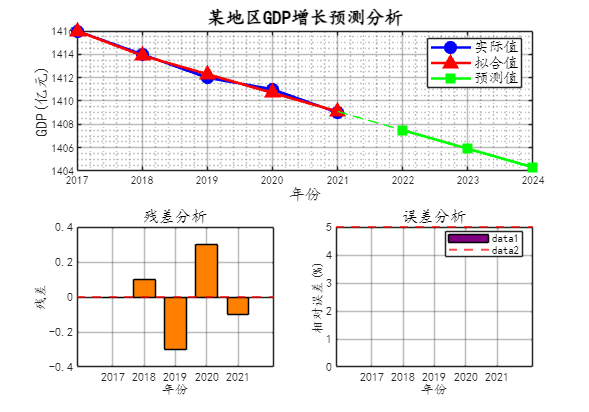

plot_results(gdp_data, years, fitted_values, future_years, predicted_values, '某地区GDP增长预测分析');


% 模型适用性评估
fprintf('\n 模型适用性评估:\n');


 模型适用性评估:


fprintf('1. 数据量检查: %d个观测值 ✓（GM(1,1)适合小样本）\n', length(gdp_data));

1. 数据量检查: 5个观测值 ✓（GM(1,1)适合小样本）


valid_ratio = true;
for i = 2:length(gdp_data)
    ratio = gdp_data(i-1)/gdp_data(i);
    if ratio < 0.818 || ratio > 1.220
        valid_ratio = false;
        break;
    end
end
fprintf('3. 精度等级: %s\n', metrics.grade);

3. 精度等级: 一级（很好）


fprintf('4. 数据趋势: 单调递减 ✓（适合GM(1,1)建模）\n');

4. 数据趋势: 单调递减 ✓（适合GM(1,1)建模）


% 风险提示
fprintf('\n  使用建议与风险提示:\n');


  使用建议与风险提示:


fprintf('• 本模型适用于短期预测（1-3年），长期预测需谨慎使用\n');

• 本模型适用于短期预测（1-3年），长期预测需谨慎使用


fprintf('• 预测结果基于历史趋势延续的假设，如遇重大政策变化或经济冲击可能失效\n');

• 预测结果基于历史趋势延续的假设，如遇重大政策变化或经济冲击可能失效


fprintf('• 建议结合其他预测方法进行对比验证\n');

• 建议结合其他预测方法进行对比验证


fprintf('• 模型精度为%s，预测结果可作为参考依据\n', metrics.grade);

• 模型精度为一级（很好），预测结果可作为参考依据



fprintf('\n============================================================\n');

fprintf('案例一：GDP增长预测 - 分析完成！\n');

案例一：GDP增长预测 - 分析完成！


fprintf('============================================================\n');